
%% Example of fitting the vanilla model - Spikefinder competition

global calcium_train spike_train X Y spks

%% read the calcium data

calcium_train = dlmread('../1.train.calcium.csv');
calcium_train(1,:) = [];        % drop first row of cell #s
ncells = size(calcium_train,2);
X = nanzscore(calcium_train);   % zscore the raw data

%% read the spikes

spike_train   = dlmread('../1.train.spikes.csv');
spike_train(1,:) = [];  % drop first row
Y = spike_train;


%% Fit the dataset by finding optimal parameters

[x,fval] = fminsearch(@predval,[10   1   2  30 ], optimset('Display','final'));

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



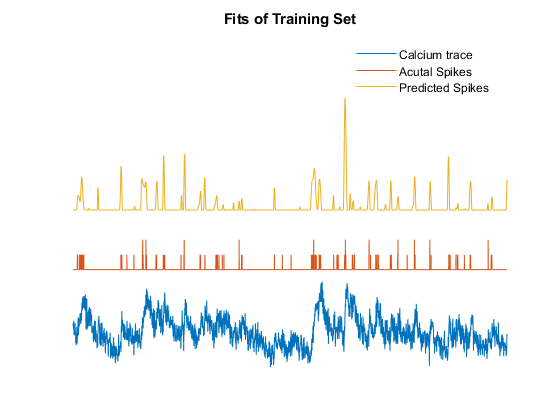


%% Generate predictions for the trained set

spks = pred(x);

%% Plot some two sample fits on the training dataset

close all
T = 20000:25000;
plot_fit(T,6);title('Fits of Training Set')

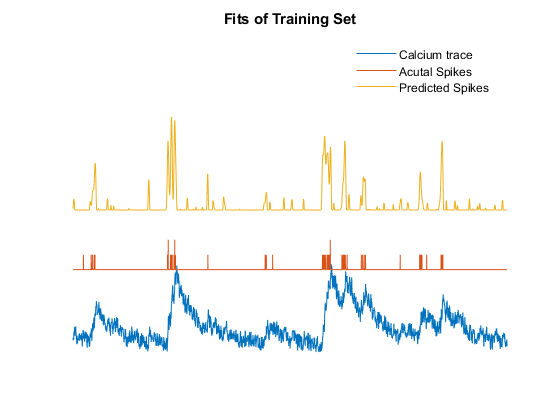

plot_fit(T,5);title('Fits of Training Set')

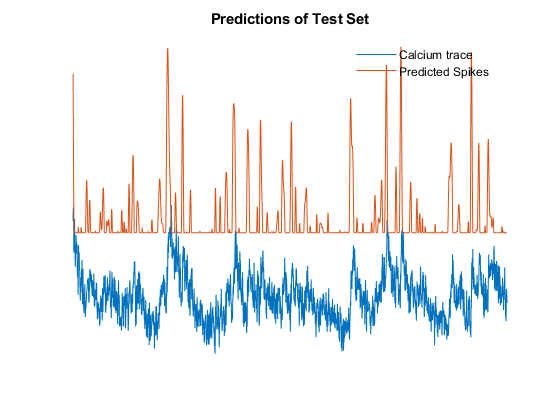



%% Generate predicitons for the test set

calcium_train = dlmread('../1.test.calcium.csv');
calcium_train(1,:) = []; % drop first row of cell #s
ncells = size(calcium_train,2);
X = nanzscore(calcium_train);
spks = pred(x);     % predict

%% Predictions on test set

T = 5000:10000;
plot_pred(T,2);title('Predictions of Test Set')

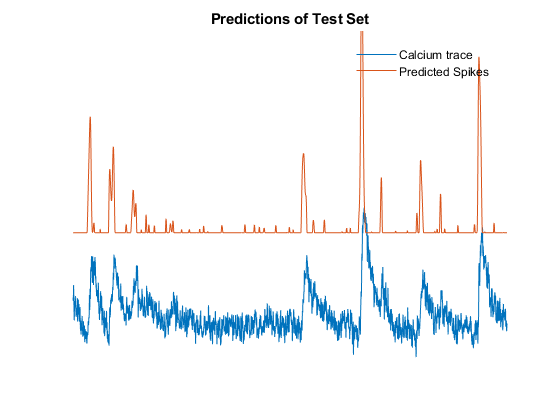

plot_pred(T,5);title('Predictions of Test Set')